images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)

ans = 2×2 table
    Label     Count
    ______    _____

    neg_64    2436 
    pos       2416 


img_classes = {'pos', 'neg_64'};

train_count = 2300

train_count = 2300

test_count = 100

test_count = 100


[images_train, images_test] = splitEachLabel(images, train_count, test_count, 'Include', img_classes);



% Przygotowanie danych treningowych
X_train = zeros(length(images_train.Files), 3780);
Y_train = images_train.Labels;

for i=1:length(images_train.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_train.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_train.Files{i});
        fprintf("Error: %s", ME);
    end
end

Extracting HOG features i=500...
Extracting HOG features i=1000...
Extracting HOG features i=1500...
Extracting HOG features i=2000...
Extracting HOG features i=2500...
Extracting HOG features i=3000...
Extracting HOG features i=3500...
Extracting HOG features i=4000...
Extracting HOG features i=4500...



% Przygotowanie danych testowych
X_test = zeros(length(images_test.Files), 3780);
Y_test = images_test.Labels;

for i=1:length(images_test.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_test.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_test(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_test.Files{i});
        fprintf("Error: %s", ME);
    end
end


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.026739 |      12.069 |    0.026739 |    0.026739 |     onevsone |        36.56 |       11.334 |
|    2 | Accept |    0.027174 |      11.582 |    0.026739 |    0.026955 |     onevsall |    0.0019573 |     0.027309 |
|    3 | Accept |    0.027174 |      11.267 |    0.026739 |    0.026739 |     onevsone |     0.004492 |     0.097381 |
|    4 | Accept |     0.16891 |      70.694 |    0.026739 |    0.026743 |     onevsall |     0.092184 |       439.38 |
|    5 | Best   |    0.026304 |      108.42 |   

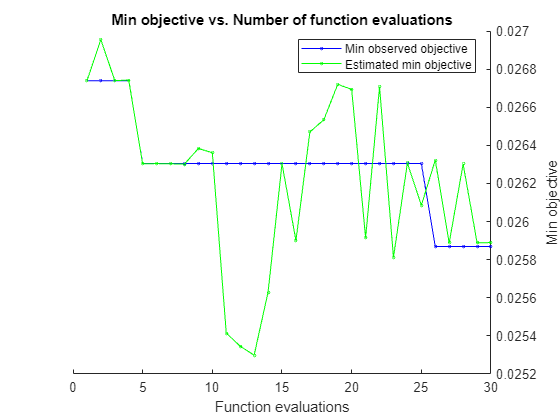


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1825.5671 seconds
Total objective function evaluation time: 1811.0918

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       989.46         0.0010056 

Observed objective function value = 0.02587
Estimated objective function value = 0.02589
Function evaluation time = 139.4319

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       989.46         0.0010056 

Estimated objective function value = 0.02589
Estimated function eval

model =   ClassificationECOC
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [neg_64    pos]
                       ScoreTransform: 'none'
                       BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
                           CodingName: 'onevsone'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Wytrenowanie klasyfikatora SVM

model = fitcecoc(X_train, Y_train,'OptimizeHyperparameters','auto', ...
      'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'))

clear loss;
loss_s = loss(model, X_test, Y_test, 'Lossfun', 'classiferror');
fprintf("loss=%f\n", loss_s);

loss=0.020000



% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 24;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 60;

dets = [];
scores = [];
labels = {};


for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

fprintf("level=%d count_x=%d count_y=%d", k, count_x, count_y)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        fprintf("level=%d %d/%d (j=%d, i=%d)... \n", k, j*count_x+i, count_y*count_x, j, i);
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        pred = model.predict(sub_hog);
        out(j+1, i+1) = strcmp(pred, 'pos');
    end
end

best_score = min(min(out))

figure;
imagesc(out)
figure;
mins = imregionalmin(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;

    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

scale = 1

count_x = 25

count_y = 11

level=1 count_x=25 count_y=11

level=1 0/275 (j=0, i=0)... 


pred=pos


level=1 1/275 (j=0, i=1)... 


pred=pos


level=1 2/275 (j=0, i=2)... 


pred=pos


level=1 3/275 (j=0, i=3)... 


pred=pos


level=1 4/275 (j=0, i=4)... 


pred=pos


level=1 5/275 (j=0, i=5)... 


pred=pos


level=1 6/275 (j=0, i=6)... 


pred=pos


level=1 7/275 (j=0, i=7)... 


pred=pos


level=1 8/275 (j=0, i=8)... 


pred=pos


level=1 9/275 (j=0, i=9)... 


pred=pos


level=1 10/275 (j=0, i=10)... 


pred=pos


level=1 11/275 (j=0, i=11)... 


pred=pos


level=1 12/275 (j=0, i=12)... 


pred=pos


level=1 13/275 (j=0, i=13)... 


pred=pos


level=1 14/275 (j=0, i=14)... 


pred=pos


level=1 15/275 (j=0, i=15)... 


pred=pos


level=1 16/275 (j=0, i=16)... 


pred=pos


level=1 17/275 (j=0, i=17)... 


pred=pos


level=1 18/275 (j=0, i=18)... 


pred=pos


level=1 19/275 (j=0, i=19)... 


pred=pos


level=1 20/275 (j=0, i=20)... 


pred=pos


level=1 21/275 (j=0, i=21)... 


pred=pos


level=1 22/275 (j=0, i=22)... 


pred=pos


level=1 23/275 (j=0, i=23)... 


pred=pos


level=1 24/275 (j=0, i=24)... 


pred=pos


level=1 25/275 (j=1, i=0)... 


pred=pos


level=1 26/275 (j=1, i=1)... 


pred=pos


level=1 27/275 (j=1, i=2)... 


pred=pos


level=1 28/275 (j=1, i=3)... 


pred=pos


level=1 29/275 (j=1, i=4)... 


pred=pos


level=1 30/275 (j=1, i=5)... 


pred=pos


level=1 31/275 (j=1, i=6)... 


pred=pos


level=1 32/275 (j=1, i=7)... 


pred=pos


level=1 33/275 (j=1, i=8)... 


pred=pos


level=1 34/275 (j=1, i=9)... 


pred=pos


level=1 35/275 (j=1, i=10)... 


pred=pos


level=1 36/275 (j=1, i=11)... 


pred=pos


level=1 37/275 (j=1, i=12)... 


pred=pos


level=1 38/275 (j=1, i=13)... 


pred=pos


level=1 39/275 (j=1, i=14)... 


pred=pos


level=1 40/275 (j=1, i=15)... 


pred=pos


level=1 41/275 (j=1, i=16)... 


pred=pos


level=1 42/275 (j=1, i=17)... 


pred=pos


level=1 43/275 (j=1, i=18)... 


pred=pos


level=1 44/275 (j=1, i=19)... 


pred=pos


level=1 45/275 (j=1, i=20)... 


pred=pos


level=1 46/275 (j=1, i=21)... 


pred=pos


level=1 47/275 (j=1, i=22)... 


pred=pos


level=1 48/275 (j=1, i=23)... 


pred=pos


level=1 49/275 (j=1, i=24)... 


pred=pos


level=1 50/275 (j=2, i=0)... 


pred=pos


level=1 51/275 (j=2, i=1)... 


pred=pos


level=1 52/275 (j=2, i=2)... 


pred=pos


level=1 53/275 (j=2, i=3)... 


pred=pos


level=1 54/275 (j=2, i=4)... 


pred=pos


level=1 55/275 (j=2, i=5)... 


pred=pos


level=1 56/275 (j=2, i=6)... 


pred=pos


level=1 57/275 (j=2, i=7)... 


pred=pos


level=1 58/275 (j=2, i=8)... 


pred=pos


level=1 59/275 (j=2, i=9)... 


pred=pos


level=1 60/275 (j=2, i=10)... 


pred=pos


level=1 61/275 (j=2, i=11)... 


pred=pos


level=1 62/275 (j=2, i=12)... 


pred=pos


level=1 63/275 (j=2, i=13)... 


pred=pos


level=1 64/275 (j=2, i=14)... 


pred=pos


level=1 65/275 (j=2, i=15)... 


pred=pos


level=1 66/275 (j=2, i=16)... 


pred=pos


level=1 67/275 (j=2, i=17)... 


pred=pos


level=1 68/275 (j=2, i=18)... 


pred=pos


level=1 69/275 (j=2, i=19)... 


pred=pos


level=1 70/275 (j=2, i=20)... 


pred=pos


level=1 71/275 (j=2, i=21)... 


pred=pos


level=1 72/275 (j=2, i=22)... 


pred=pos


level=1 73/275 (j=2, i=23)... 


pred=pos


level=1 74/275 (j=2, i=24)... 


pred=pos


level=1 75/275 (j=3, i=0)... 


pred=pos


level=1 76/275 (j=3, i=1)... 


pred=pos


level=1 77/275 (j=3, i=2)... 


pred=pos


level=1 78/275 (j=3, i=3)... 


pred=pos


level=1 79/275 (j=3, i=4)... 


pred=pos


level=1 80/275 (j=3, i=5)... 


pred=pos


level=1 81/275 (j=3, i=6)... 


pred=pos


level=1 82/275 (j=3, i=7)... 


pred=pos


level=1 83/275 (j=3, i=8)... 


pred=pos


level=1 84/275 (j=3, i=9)... 


pred=pos


level=1 85/275 (j=3, i=10)... 


pred=pos


level=1 86/275 (j=3, i=11)... 


pred=pos


level=1 87/275 (j=3, i=12)... 


pred=pos


level=1 88/275 (j=3, i=13)... 


pred=pos


level=1 89/275 (j=3, i=14)... 


pred=pos


level=1 90/275 (j=3, i=15)... 


pred=pos


level=1 91/275 (j=3, i=16)... 


pred=pos


level=1 92/275 (j=3, i=17)... 


pred=pos


level=1 93/275 (j=3, i=18)... 


pred=pos


level=1 94/275 (j=3, i=19)... 


pred=pos


level=1 95/275 (j=3, i=20)... 


pred=pos


level=1 96/275 (j=3, i=21)... 


pred=pos


level=1 97/275 (j=3, i=22)... 


pred=pos


level=1 98/275 (j=3, i=23)... 


pred=pos


level=1 99/275 (j=3, i=24)... 


pred=pos


level=1 100/275 (j=4, i=0)... 


pred=pos


level=1 101/275 (j=4, i=1)... 


pred=pos


level=1 102/275 (j=4, i=2)... 


pred=pos


level=1 103/275 (j=4, i=3)... 


pred=pos


level=1 104/275 (j=4, i=4)... 


pred=pos


level=1 105/275 (j=4, i=5)... 


pred=pos


level=1 106/275 (j=4, i=6)... 


pred=pos


level=1 107/275 (j=4, i=7)... 


pred=pos


level=1 108/275 (j=4, i=8)... 


pred=pos


level=1 109/275 (j=4, i=9)... 


pred=pos


level=1 110/275 (j=4, i=10)... 


pred=pos


level=1 111/275 (j=4, i=11)... 


pred=pos


level=1 112/275 (j=4, i=12)... 


pred=pos


level=1 113/275 (j=4, i=13)... 


pred=pos


level=1 114/275 (j=4, i=14)... 


pred=pos


level=1 115/275 (j=4, i=15)... 


pred=pos


level=1 116/275 (j=4, i=16)... 


pred=pos


level=1 117/275 (j=4, i=17)... 


pred=pos


level=1 118/275 (j=4, i=18)... 


pred=pos


level=1 119/275 (j=4, i=19)... 


pred=pos


level=1 120/275 (j=4, i=20)... 


pred=pos


level=1 121/275 (j=4, i=21)... 


pred=pos


level=1 122/275 (j=4, i=22)... 


pred=pos


level=1 123/275 (j=4, i=23)... 


pred=pos


level=1 124/275 (j=4, i=24)... 


pred=pos


level=1 125/275 (j=5, i=0)... 


pred=pos


level=1 126/275 (j=5, i=1)... 


pred=pos


level=1 127/275 (j=5, i=2)... 


pred=pos


level=1 128/275 (j=5, i=3)... 


pred=pos


level=1 129/275 (j=5, i=4)... 


pred=pos


level=1 130/275 (j=5, i=5)... 


pred=pos


level=1 131/275 (j=5, i=6)... 


pred=pos


level=1 132/275 (j=5, i=7)... 


pred=pos


level=1 133/275 (j=5, i=8)... 


pred=pos


level=1 134/275 (j=5, i=9)... 


pred=pos


level=1 135/275 (j=5, i=10)... 


pred=pos


level=1 136/275 (j=5, i=11)... 


pred=pos


level=1 137/275 (j=5, i=12)... 


pred=pos


level=1 138/275 (j=5, i=13)... 


pred=pos


level=1 139/275 (j=5, i=14)... 


pred=pos


level=1 140/275 (j=5, i=15)... 


pred=pos


level=1 141/275 (j=5, i=16)... 


pred=pos


level=1 142/275 (j=5, i=17)... 


pred=pos


level=1 143/275 (j=5, i=18)... 


pred=pos


level=1 144/275 (j=5, i=19)... 


pred=pos


level=1 145/275 (j=5, i=20)... 


pred=pos


level=1 146/275 (j=5, i=21)... 


pred=pos


level=1 147/275 (j=5, i=22)... 


pred=pos


level=1 148/275 (j=5, i=23)... 


pred=pos


level=1 149/275 (j=5, i=24)... 


pred=pos


level=1 150/275 (j=6, i=0)... 


pred=pos


level=1 151/275 (j=6, i=1)... 


pred=pos


level=1 152/275 (j=6, i=2)... 


pred=pos


level=1 153/275 (j=6, i=3)... 


pred=pos


level=1 154/275 (j=6, i=4)... 


pred=pos


level=1 155/275 (j=6, i=5)... 


pred=pos


level=1 156/275 (j=6, i=6)... 


pred=pos


level=1 157/275 (j=6, i=7)... 


pred=pos


level=1 158/275 (j=6, i=8)... 


pred=pos


level=1 159/275 (j=6, i=9)... 


pred=pos


level=1 160/275 (j=6, i=10)... 


pred=pos


level=1 161/275 (j=6, i=11)... 


pred=pos


level=1 162/275 (j=6, i=12)... 


pred=pos


level=1 163/275 (j=6, i=13)... 


pred=pos


level=1 164/275 (j=6, i=14)... 


pred=pos


level=1 165/275 (j=6, i=15)... 


pred=pos


level=1 166/275 (j=6, i=16)... 


pred=pos


level=1 167/275 (j=6, i=17)... 


pred=pos


level=1 168/275 (j=6, i=18)... 


pred=pos


level=1 169/275 (j=6, i=19)... 


pred=pos


level=1 170/275 (j=6, i=20)... 


pred=pos


level=1 171/275 (j=6, i=21)... 


pred=pos


level=1 172/275 (j=6, i=22)... 


pred=pos


level=1 173/275 (j=6, i=23)... 


pred=pos


level=1 174/275 (j=6, i=24)... 


pred=pos


level=1 175/275 (j=7, i=0)... 


pred=pos


level=1 176/275 (j=7, i=1)... 


pred=pos


level=1 177/275 (j=7, i=2)... 


pred=pos


level=1 178/275 (j=7, i=3)... 


pred=pos


level=1 179/275 (j=7, i=4)... 


pred=pos


level=1 180/275 (j=7, i=5)... 


pred=pos


level=1 181/275 (j=7, i=6)... 


pred=pos


level=1 182/275 (j=7, i=7)... 


pred=pos


level=1 183/275 (j=7, i=8)... 


pred=pos


level=1 184/275 (j=7, i=9)... 


pred=pos


level=1 185/275 (j=7, i=10)... 


pred=pos


level=1 186/275 (j=7, i=11)... 


pred=pos


level=1 187/275 (j=7, i=12)... 


pred=pos


level=1 188/275 (j=7, i=13)... 


pred=pos


level=1 189/275 (j=7, i=14)... 


pred=pos


level=1 190/275 (j=7, i=15)... 


pred=pos


level=1 191/275 (j=7, i=16)... 


pred=pos


level=1 192/275 (j=7, i=17)... 


pred=pos


level=1 193/275 (j=7, i=18)... 


pred=pos


level=1 194/275 (j=7, i=19)... 


pred=pos


level=1 195/275 (j=7, i=20)... 


pred=pos


level=1 196/275 (j=7, i=21)... 


pred=pos


level=1 197/275 (j=7, i=22)... 


pred=pos


level=1 198/275 (j=7, i=23)... 


pred=pos


level=1 199/275 (j=7, i=24)... 


pred=pos


level=1 200/275 (j=8, i=0)... 


pred=pos


level=1 201/275 (j=8, i=1)... 


pred=pos


level=1 202/275 (j=8, i=2)... 


pred=pos


level=1 203/275 (j=8, i=3)... 


pred=pos


level=1 204/275 (j=8, i=4)... 


pred=pos


level=1 205/275 (j=8, i=5)... 


pred=pos


level=1 206/275 (j=8, i=6)... 


pred=pos


level=1 207/275 (j=8, i=7)... 


pred=pos


level=1 208/275 (j=8, i=8)... 


pred=pos


level=1 209/275 (j=8, i=9)... 


pred=pos


level=1 210/275 (j=8, i=10)... 


pred=pos


level=1 211/275 (j=8, i=11)... 


pred=pos


level=1 212/275 (j=8, i=12)... 


pred=pos


level=1 213/275 (j=8, i=13)... 


pred=pos


level=1 214/275 (j=8, i=14)... 


pred=pos


level=1 215/275 (j=8, i=15)... 


pred=pos


level=1 216/275 (j=8, i=16)... 


pred=pos


level=1 217/275 (j=8, i=17)... 


pred=pos


level=1 218/275 (j=8, i=18)... 


pred=pos


level=1 219/275 (j=8, i=19)... 


pred=pos


level=1 220/275 (j=8, i=20)... 


pred=pos


level=1 221/275 (j=8, i=21)... 


pred=pos


level=1 222/275 (j=8, i=22)... 


pred=pos


level=1 223/275 (j=8, i=23)... 


pred=pos


level=1 224/275 (j=8, i=24)... 


pred=pos


level=1 225/275 (j=9, i=0)... 


pred=pos


level=1 226/275 (j=9, i=1)... 


pred=pos


level=1 227/275 (j=9, i=2)... 


pred=pos


level=1 228/275 (j=9, i=3)... 


pred=pos


level=1 229/275 (j=9, i=4)... 


pred=pos


level=1 230/275 (j=9, i=5)... 


pred=pos


level=1 231/275 (j=9, i=6)... 


pred=pos


level=1 232/275 (j=9, i=7)... 


pred=pos


level=1 233/275 (j=9, i=8)... 


pred=pos


level=1 234/275 (j=9, i=9)... 


pred=pos


level=1 235/275 (j=9, i=10)... 


pred=pos


level=1 236/275 (j=9, i=11)... 


pred=pos


level=1 237/275 (j=9, i=12)... 


pred=pos


level=1 238/275 (j=9, i=13)... 


pred=pos


level=1 239/275 (j=9, i=14)... 


pred=pos


level=1 240/275 (j=9, i=15)... 


pred=pos


level=1 241/275 (j=9, i=16)... 


pred=pos


level=1 242/275 (j=9, i=17)... 


pred=pos


level=1 243/275 (j=9, i=18)... 


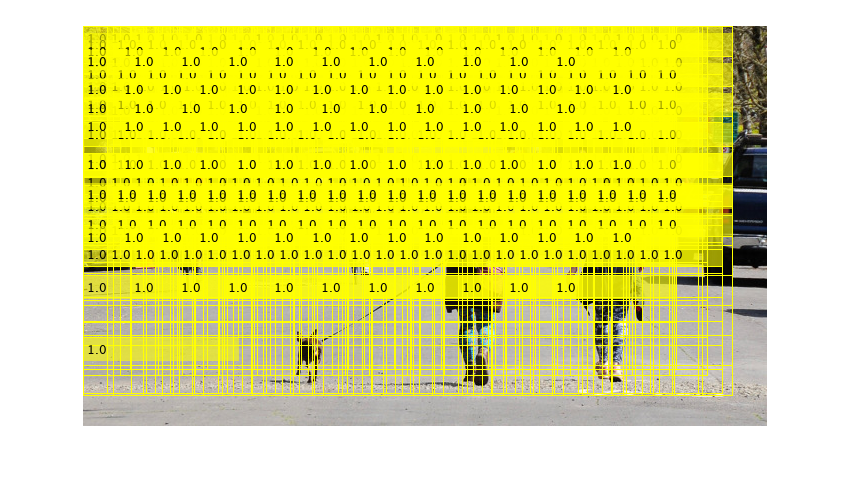

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

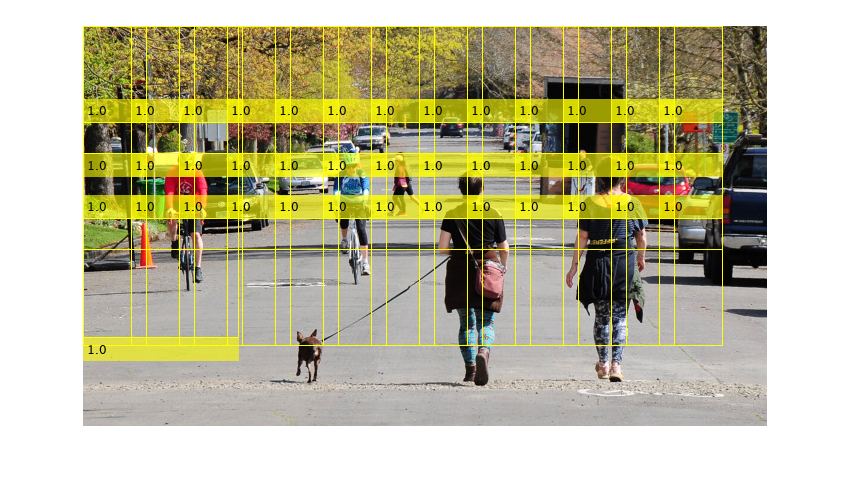

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

gt_rect=gTruth.LabelData.person{1,1};

Unable to resolve the name 'gTruth.LabelData.person'.

ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);
score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)
[best_overlaps, good_ids] = max(ratio, [], 2)
iou = 0.4;
best_ids = good_ids(best_overlaps > iou)
pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");
figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");
ap = trapz(R, P)

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end